## Problem 15

omega = 15;
zeta = 1;
T1 = 0;
T2 = -36.8734;
T3 = 60.3195;
T4 = -10.5752;
Jeff1=0.0198; % kgm^2
Jeff2=0.0242; % kgm^2
Jeff3=0.0027; % kgm^2
Jeff4=0.00038; % kgm^2
qr_1 = 0.35; % rad/s
qr_2 = 0.35; % rad/s
qr_3 = 0.35; % m
qr_4 = 0.35; % rad/s
k_T = 0.17 % Nm/V

k_T = 0.1700

f = 0.000024 % Nm/(rad/s)

f = 2.4000e-05

n=53;

Kd_1 = 9.3763

Kd_1 = 9.3763

Kd_2 = 10.1528

Kd_2 = 10.1528

Kd_3 = 6.35869

Kd_3 = 6.3587

Kd_4 = 5.94927

Kd_4 = 5.9493


Kp_1 = 202.6765

Kp_1 = 202.6765

Kp_2 = 208.5

Kp_2 = 208.5000

Kp_3 = 180.0441

Kp_3 = 180.0441

Kp_4 = 176.9735

Kp_4 = 176.9735


Ki_1 = 1323.5294

Ki_1 = 1.3235e+03

Ki_2 = 1323.5294

Ki_2 = 1.3235e+03

Ki_3 = 1323.5294

Ki_3 = 1.3235e+03

Ki_4 = 1323.5294

Ki_4 = 1.3235e+03


J1=Jeff1/k_T

J1 = 0.1165

J2=Jeff2/k_T

J2 = 0.1424

J3=Jeff3/k_T

J3 = 0.0159

J4=Jeff4/k_T

J4 = 0.0022


B=f/k_T

B = 1.4118e-04

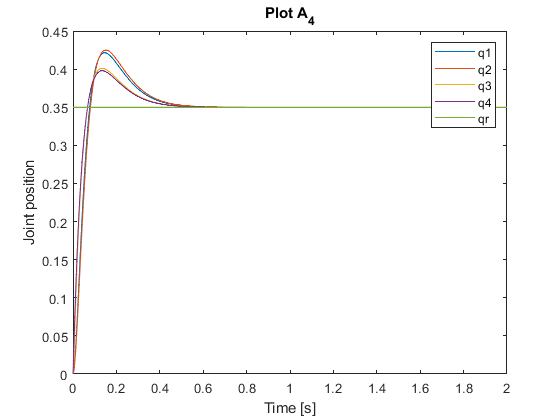

simulink = sim('problem15.slx',2);   % start simulation
%open_system('problem12/Scope')   % open scope
q1 = simulink.get('q1');
q2 = simulink.get('q2');
q3 = simulink.get('q3');
q4 = simulink.get('q4');
qrData=ones(length(q4.Data),1)*0.35;
plot(q1.Time,q1.Data), hold on
plot(q2.Time,q2.Data), hold on
plot(q3.Time,q3.Data), hold on
plot(q4.Time,q4.Data), hold on
plot(q4.Time,qrData)
legend('q1','q2','q3','q4','qr')
xlabel('Time [s]') 
ylabel('Joint position')
title('Plot A_4')
hold off

## Problem 16

B=f/k_T

B = 1.4118e-04

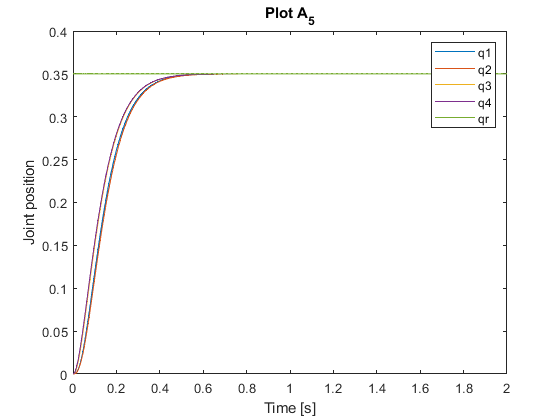

simulink = sim('problem16.slx',2);   % start simulation
%open_system('problem12/Scope')   % open scope
q1 = simulink.get('q1');
q2 = simulink.get('q2');
q3 = simulink.get('q3');
q4 = simulink.get('q4');
qrData=ones(length(q4.Data),1)*0.35;
plot(q1.Time,q1.Data), hold on
plot(q2.Time,q2.Data), hold on
plot(q3.Time,q3.Data), hold on
plot(q4.Time,q4.Data), hold on
plot(q4.Time,qrData)
legend('q1','q2','q3','q4','qr')
xlabel('Time [s]') 
ylabel('Joint position')
title('Plot A_5')